# Confidence Interval Plot Examples

Create a mean line within a shaded confidence interval area.

## Plot a 95% confidence interval plot for x-values with repeated y-values

Generate unique x data. For each unique x-value, let the data have 3 data points with the same x-value and a y-value of sin(x) with random noise.

uniqueX = -2 * pi : pi/4 : 2*pi;
x = repelem(uniqueX, 3);
y = sin(x) + 0.5 * rand(size(x));

Create the bounded line for the data. Adjust the confidence interval plot to have a smoother mean line and smoother boundaries using a higher number of points for interpolation.

cip = confidenceIntervalPlot(x,y);
cip.NumSteps = 2;

Adjust the line and boundary to be even smoother.

cip.NumSteps = 50;

Set the title and subtitle.

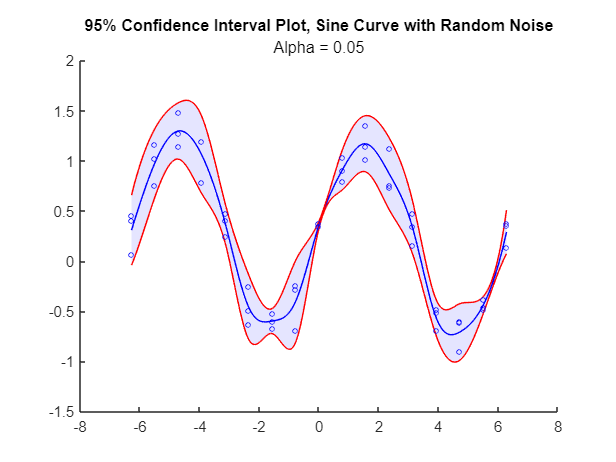

title("95% Confidence Interval Plot, Sine Curve with Random Noise");
subtitle("Alpha = 0.05");

## Plot with custom bounds and center line data

centerYData = cip.CenterYData;
cip = confidenceIntervalPlot(x, y, ...
    'BoundDataMode', 'manual', ...
    'UpperBoundData', centerYData + 0.5, ...
    'LowerBoundData', centerYData - 0.5, ...
    'NumSteps', 50);

Show the data used to generate the center line. Set the title.

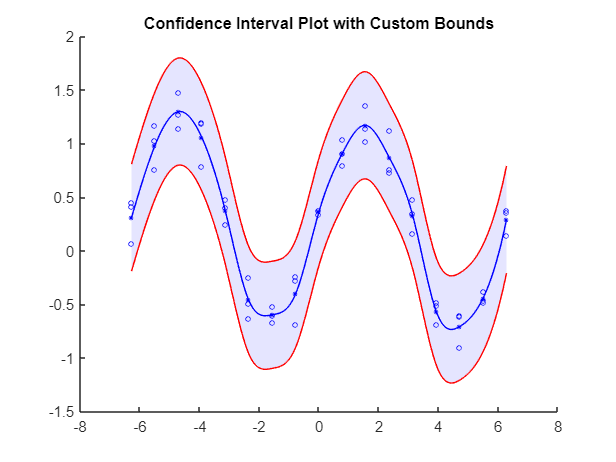

cip.ShowCenterData = true;

title("Confidence Interval Plot with Custom Bounds");

## Plot a 90% confidence interval plot using bins for data

Generate x data which are clustered around each integer from 1 to 10.

uniqueX = 1:10;
x = repelem(uniqueX, 3);
x = x + 0.5 * rand(size(x));

For each x-value, compute the y value with noise.

y = sin(x) + 0.5 * rand(size(x));

Create the confidence interval plot for the data. Specify an alpha level of 0.1 (90% confidence interval) and specify bins edges to be integers from 1 to 10.

Set the title and subtitle.

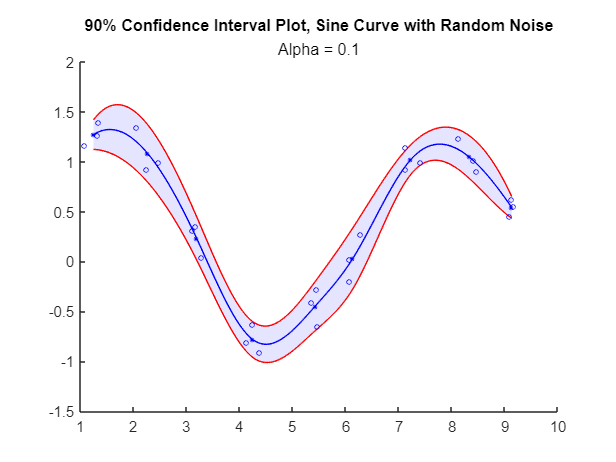

cip = confidenceIntervalPlot(x, y, 0.1, 'edges', 1:10, 'NumSteps', 50, ...
    'ShowCenterData', true);

title("90% Confidence Interval Plot, Sine Curve with Random Noise");
subtitle("Alpha = 0.1");

## Change graphics properties

Change some of the visual aspects of the plot.

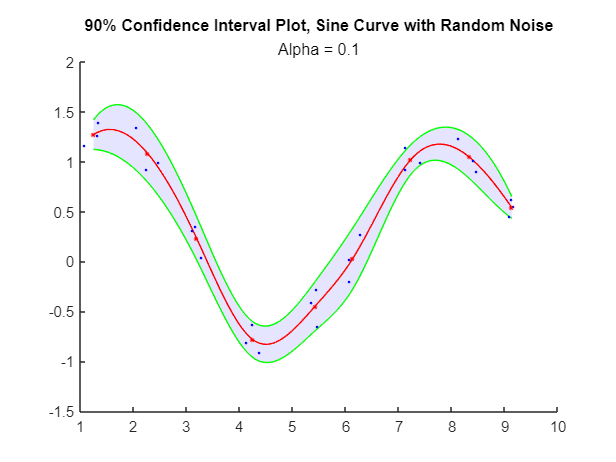

cip.CenterLineWidth = 1;
cip.CenterLineColor = [1 0 0];
cip.RawDataMarker = '.';
cip.RawDataMarkerSize = 30;
cip.CenterDataMarkerColor = [1 0 0];
cip.BorderLinesColor = [0 1 0];

## Example with NaN data

uniqueX = 1:10;
X = repelem(uniqueX, 3);
Y = 2 * X + 2 * rand(size(X));

Set 1 y-value corresponding to x = 3 to NaN.

Set y-values corresponding to x = 4 and x = 7 to all NaN. 

Then for x = 3, the NaN y-value is ignored in computing the center line, boundary lines, and shaded area. However, for x = 4 and x = 7, a break in the lines and shaded area is produced.

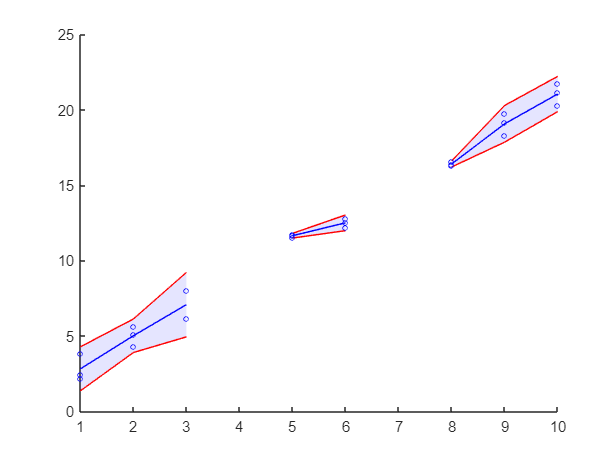

Y(9:12) = NaN;
Y(19:21) = NaN;

cip = confidenceIntervalPlot(X, Y);